clear;
for i = 1:3
    for j = 1:3
        for k = 1:5
            A(i,j,k) = i + 2*j;
        end
    end
end

A

A = A(:,:,1) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,2) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,3) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,4) =

     3     5     7
     4     6     8
     5     7     9


A(:,:,5) =

     3     5     7
     4     6     8
     5     7     9



B = reshape(A,[],5)

B =      3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5
     5     5     5     5     5
     6     6     6     6     6
     7     7     7     7     7
     7     7     7     7     7
     8     8     8     8     8
     9     9     9     9     9


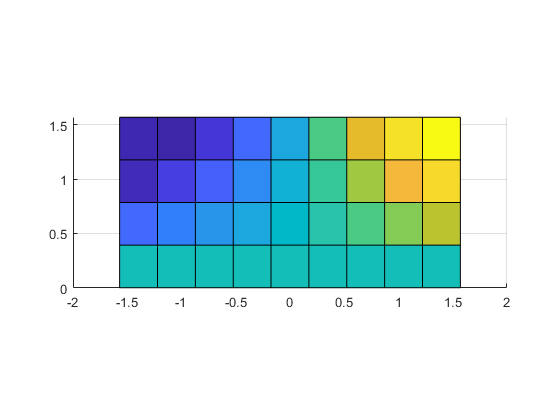

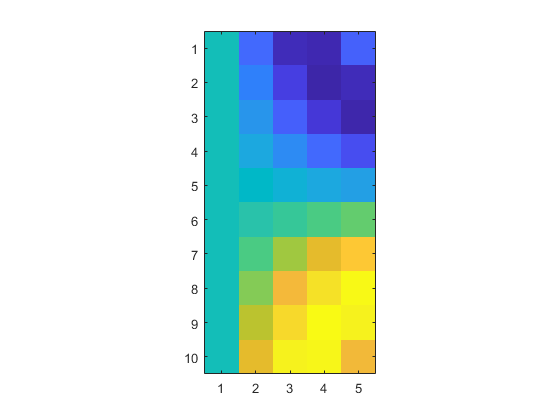


clear;
M = 10;
N = 5;
orig_dom_X1 = linspace(-pi/2,pi/2,M);
orig_dom_Y1 = linspace(0,pi/2,N);
[X,Y] = ndgrid(orig_dom_X1,orig_dom_Y1);

for i = 1:88
    m = rand;
    b = rand;
    A(:,:,i) = m*sin(X.*Y) + b;
end
surf(X,Y,A(:,:,5))
daspect([1 1 1])
view(2)


s = size(A);

B = reshape(A,[],s(end))

B =     0.8594    0.2038    0.0936    0.2152    0.3397    0.5068    0.3946    0.6065    0.4015    0.9205    0.2856    0.1428    0.6107    0.3833    0.8873    0.1382    0.4217    0.9591    0.9810    0.0962    0.5003    0.9766    0.4009    0.2610    0.9643    0.2992    0.0015    0.4044    0.9506    0.2876    0.5822    0.0731    0.2870    0.7248    0.3479    0.9536    0.7682    0.9189    0.7021    0.3851    0.0368    0.6451    0.5179    0.2975    0.8914    0.2099    0.8879    0.9668    0.1653    0.6557
    0.8594    0.2038    0.0936    0.2152    0.3397    0.5068    0.3946    0.6065    0.4015    0.9205    0.2856    0.1428    0.6107    0.3833    0.8873    0.1382    0.4217    0.9591    0.9810    0.0962    0.5003    0.9766    0.4009    0.2610    0.9643    0.2992    0.0015    0.4044    0.9506    0.2876    0.5822    0.0731    0.2870    0.7248    0.3479    0.9536    0.7682    0.9189    0.7021    0.3851    0.0368    0.6451    0.5179    0.2975    0.8914    0.2099    0.8879    0.9668    0.1653    0

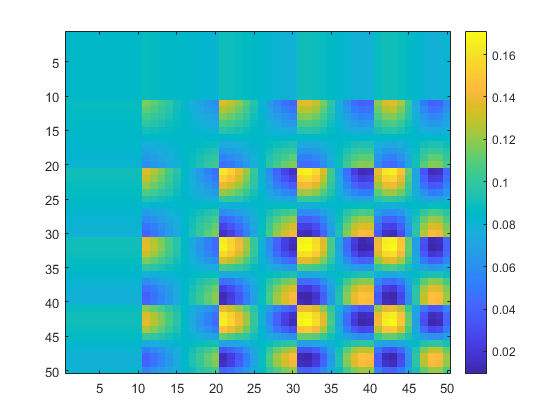

B = B';

C_B = cov(B);
imagesc(C_B)
colorbar


% 'If I reshape this^ image correctly, I should get a 4D array that varies smoothly on each of its 4 axes'
disp(['If I reshape this^ image correctly,' newline 'I should get a 4D array that ' newline 'varies smoothly on each of its 4 axes.'])

If I reshape this^ image correctly,
I should get a 4D array that 
varies smoothly on each of its 4 axes.



disp(['A good way to check if I''m reshaping it' newline 'properly or not would be to' newline 'reshape, interpolate, reshape, and plot.'])

A good way to check if I'm reshaping it
properly or not would be to
reshape, interpolate, reshape, and plot.



C = reshape(C_B,M,N,M,N);
disp('size of C')

size of C


size(C)

ans =     10     5    10     5


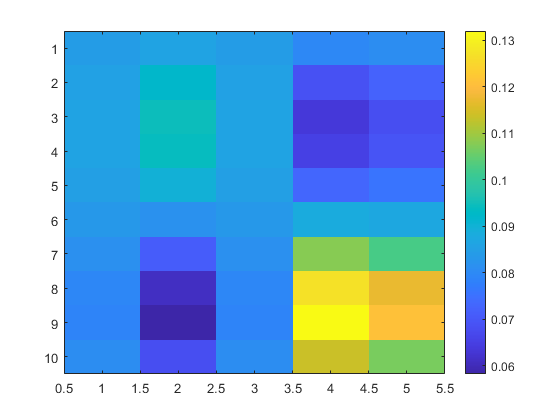


N_h = 10;
M_h = 5;

new_dom_X1 = linspace(-pi/2,pi/2,N_h);
new_dom_Y1 = linspace(0,pi/2,N_h);
new_dom_X2 = linspace(-pi/2,pi/2,M_h);
new_dom_Y2 = linspace(0,pi/2,M_h);

% [X1_h,Y1_h,X2_h,Y2_h] = ndgrid(new_dom_X1,new_dom_Y1,new_dom_X2,new_dom_Y2);
wv_i = [new_dom_X1; new_dom_Y1]; wv_j = [new_dom_X2; new_dom_Y2];

C_B_high_def = covariance_function(wv_i',wv_j',orig_dom_X1,orig_dom_Y1,C_B);

imagesc(C_B_high_def)
% daspect([1 1 1])
colorbar


disp('This is awesome and meta.')

This is awesome and meta.
